## **Import covid dashboard data**

[https://www.cancerdata.nhs.uk/covid-19/sact](https://www.cancerdata.nhs.uk/covid-19/sact) 

covid_data = readtable("SACTcovid19dashboarddata.csv");

## filter all england monthly activity data

use strcmp to filter data matching the criteria in string

use & as AND 

all_england_monthly_activity2019 = covid_data(strcmp(covid_data.activity_level, 'Monthly activity') & strcmp(covid_data.geo_lvl, 'National') & strcmp(covid_data.geo_val, 'All England') & covid_data.activity_year == 2019,:);
all_england_monthly_activity2020 = covid_data(strcmp(covid_data.activity_level, 'Monthly activity') & strcmp(covid_data.geo_lvl, 'National') & strcmp(covid_data.geo_val, 'All England') & covid_data.activity_year == 2020,:);
all_england_monthly_activity2021 = covid_data(strcmp(covid_data.activity_level, 'Monthly activity') & strcmp(covid_data.geo_lvl, 'National') & strcmp(covid_data.geo_val, 'All England') & covid_data.activity_year == 2021,:);
calendar_month = 1:12;

## Plot 

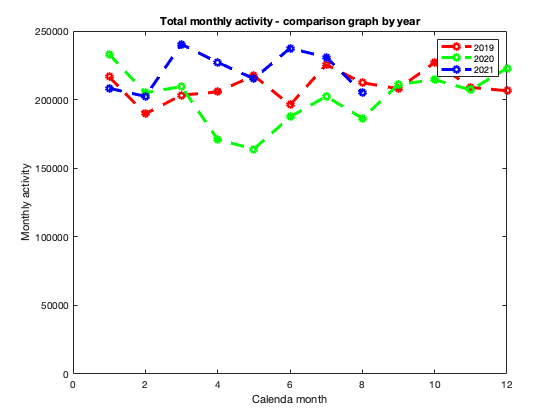

plot(calendar_month, all_england_monthly_activity2019.activity_count, 'r--o', 'LineWidth', 3);
hold on;
plot(calendar_month, all_england_monthly_activity2020.activity_count, 'g--o', 'LineWidth', 3);
% vector can use the method in the following line to add NaN
% elements to make up the same length of other vectors
plot(calendar_month, [all_england_monthly_activity2021.activity_count; repelem(NaN, 4)'], 'b--o', 'LineWidth', 3);
ylim([0 250000]);
xlabel("Calenda month");
ylabel("Monthly activity");
legend('2019','2020','2021');
ax = gca;
ax.YAxis.Exponent = 0;
title("Total monthly activity - comparison graph by year");
hold off;